emissions = CO2flat;

% Extract only France’s rows
france_data = emissions(18907:19180, :);

% Remove the first 60 rows once (starting at year 1810)
france_data(1:60, :) = [];

% If you want year + total separately:
france_year_total = france_data(:, 4:5);

% Display data before cleaning
disp("data before replacing 0 with NaN: ")

data before replacing 0 with NaN: 


disp(france_data)

    Country    ISO31661Alpha3    UNM49    Year    Total      Coal       Oil         Gas       Cement     Flaring      Other       PerCapita
    _______    ______________    _____    ____    ______    ______    ________    ________    _______    _______    __________    _________

    France          FRA           250     1810    2.1215    2.1215           0           0        NaN        NaN    ""            0.070452 
    France          FRA           250     1811    2.0518    2.0518           0           0        NaN        NaN    ""            0.067886 
    France          FRA        


% Make a copy to do the cleaning in 
france_clean = france_data;

% Find numeric columns
numCols = varfun(@isnumeric, france_clean, 'OutputFormat', 'uniform');

% Loop through numeric columns and replace 0 with NaN
for c = find(numCols)
    colData = france_clean{:,c};
    colData(colData == 0) = NaN;
    france_clean{:,c} = colData;
end

% Display data after cleaning
disp("data after replacing 0 with NaN")

data after replacing 0 with NaN


disp(france_clean)

    Country    ISO31661Alpha3    UNM49    Year    Total      Coal       Oil         Gas       Cement     Flaring      Other       PerCapita
    _______    ______________    _____    ____    ______    ______    ________    ________    _______    _______    __________    _________

    France          FRA           250     1810    2.1215    2.1215         NaN         NaN        NaN        NaN    ""            0.070452 
    France          FRA           250     1811    2.0518    2.0518         NaN         NaN        NaN        NaN    ""            0.067886 
    France          FRA        


%STEP 2: INTERPOLATION
% Columns of interest
cols = {'Coal','Oil','Gas','Cement','Flaring'};

% Copy tables for each interpolation method
france_linear = france_clean;
france_spline = france_clean;
france_pchip  = france_clean;

% Loop over each column
for i = 1:numel(cols)
    col = cols{i};
    
    % Extract column as array
    y = france_clean.(col);
    
    % Only interpolate missing values (NaNs)
    if isnumeric(y)
        % Linear interpolation of NaNs only
        france_linear.(col) = fillmissing(y, 'linear', 'EndValues', 'none');
        
        % Spline interpolation of NaNs only
        france_spline.(col) = fillmissing(y, 'spline', 'EndValues', 'none');
        
        % Shape-preserving cubic interpolation of NaNs only
        france_pchip.(col)  = fillmissing(y, 'pchip', 'EndValues', 'none');
    end
end

% --- Example: Display results for first 10 rows ---

disp('Linear interpolation (NaNs filled only):')

Linear interpolation (NaNs filled only):


disp(france_linear(1:10, [cols, {'Total'}]))

     Coal     Oil    Gas    Cement    Flaring    Total 
    ______    ___    ___    ______    _______    ______

    2.1215    NaN    NaN     NaN        NaN      2.1215
    2.0518    NaN    NaN     NaN        NaN      2.0518
    2.2167    NaN    NaN     NaN        NaN      2.2167
    2.0482    NaN    NaN     NaN        NaN      2.0482
    2.0921    NaN    NaN     NaN        NaN      2.0921
    2.3413    NaN    NaN     NaN        NaN      2.3413
    2.4988    NaN    NaN     NaN        NaN      2.4988
    2.6601    NaN    NaN     NaN        NaN      2.6601
    2.3816    NaN    NaN     NaN        NaN      2.3816
    2.5575    NaN    NaN     NaN        NaN      2.5575




disp('Spline interpolation (NaNs filled only):')

Spline interpolation (NaNs filled only):


disp(france_spline(1:10, [cols, {'Total'}]))

     Coal     Oil    Gas    Cement    Flaring    Total 
    ______    ___    ___    ______    _______    ______

    2.1215    NaN    NaN     NaN        NaN      2.1215
    2.0518    NaN    NaN     NaN        NaN      2.0518
    2.2167    NaN    NaN     NaN        NaN      2.2167
    2.0482    NaN    NaN     NaN        NaN      2.0482
    2.0921    NaN    NaN     NaN        NaN      2.0921
    2.3413    NaN    NaN     NaN        NaN      2.3413
    2.4988    NaN    NaN     NaN        NaN      2.4988
    2.6601    NaN    NaN     NaN        NaN      2.6601
    2.3816    NaN    NaN     NaN        NaN      2.3816
    2.5575    NaN    NaN     NaN        NaN      2.5575




disp('PCHIP interpolation (NaNs filled only):')

PCHIP interpolation (NaNs filled only):


disp(france_pchip(1:10, [cols, {'Total'}]))

     Coal     Oil    Gas    Cement    Flaring    Total 
    ______    ___    ___    ______    _______    ______

    2.1215    NaN    NaN     NaN        NaN      2.1215
    2.0518    NaN    NaN     NaN        NaN      2.0518
    2.2167    NaN    NaN     NaN        NaN      2.2167
    2.0482    NaN    NaN     NaN        NaN      2.0482
    2.0921    NaN    NaN     NaN        NaN      2.0921
    2.3413    NaN    NaN     NaN        NaN      2.3413
    2.4988    NaN    NaN     NaN        NaN      2.4988
    2.6601    NaN    NaN     NaN        NaN      2.6601
    2.3816    NaN    NaN     NaN        NaN      2.3816
    2.5575    NaN    NaN     NaN        NaN      2.5575



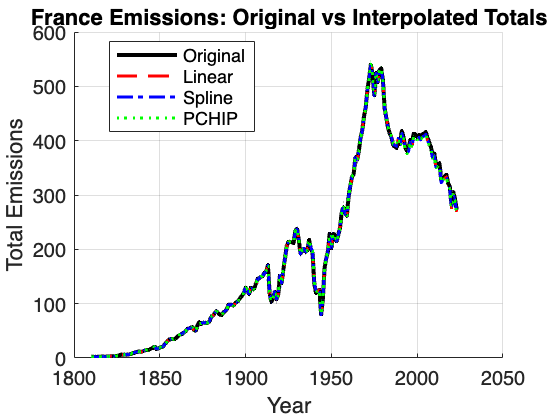



%Creating New Totals
% Columns that make up the total
cols = {'Coal','Oil','Gas','Cement','Flaring'};

% Recompute Total for each interpolated dataset
france_linear.Total = sum(france_linear{:,cols}, 2, 'omitnan');
france_spline.Total = sum(france_spline{:,cols}, 2, 'omitnan');
france_pchip.Total  = sum(france_pchip{:,cols}, 2, 'omitnan');

% Extract the year column (adjust name if your table calls it something else)
years = france_data.Year;

% Original total
orig_total = france_data.Total;

% Recomputed totals after interpolation
linear_total  = france_linear.Total;
spline_total  = france_spline.Total;
pchip_total   = france_pchip.Total;

% --- Plot ---
figure;
hold on;

plot(years, orig_total, 'k-', 'LineWidth', 2, 'DisplayName', 'Original');
plot(years, linear_total, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Linear');
plot(years, spline_total, 'b-.', 'LineWidth', 1.5, 'DisplayName', 'Spline');
plot(years, pchip_total, 'g:', 'LineWidth', 1.5, 'DisplayName', 'PCHIP');

hold off;

xlabel('Year');
ylabel('Total Emissions');
title('France Emissions: Original vs Interpolated Totals');
legend('Location','best');
grid on;

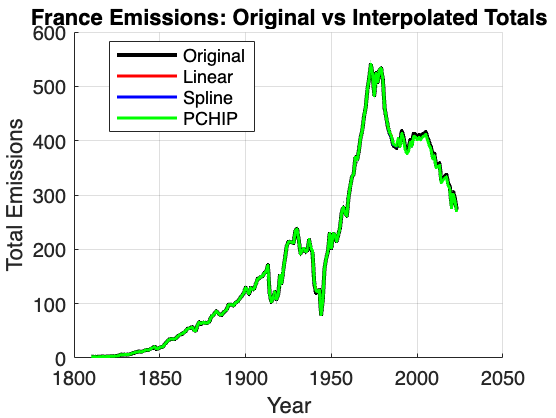


% Extract the year column (adjust name if your table calls it something else)
years = france_data.Year;

% Original total
orig_total = france_data.Total;

% Recomputed totals after interpolation
linear_total  = france_linear.Total;
spline_total  = france_spline.Total;
pchip_total   = france_pchip.Total;

% Extract the year column (adjust if your table calls it something else)
years = france_data.Year;

% Original total
orig_total = france_data.Total;

% Recomputed totals after interpolation
linear_total  = france_linear.Total;
spline_total  = france_spline.Total;
pchip_total   = france_pchip.Total;

% --- Plot all with solid lines and different colors ---
figure;
hold on;

plot(years, orig_total, 'k-', 'LineWidth', 2, 'DisplayName', 'Original');
plot(years, linear_total, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Linear');
plot(years, spline_total, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Spline');
plot(years, pchip_total, 'g-', 'LineWidth', 1.5, 'DisplayName', 'PCHIP');

hold off;

xlabel('Year');
ylabel('Total Emissions');
title('France Emissions: Original vs Interpolated Totals');
legend('Location','best');
grid on;

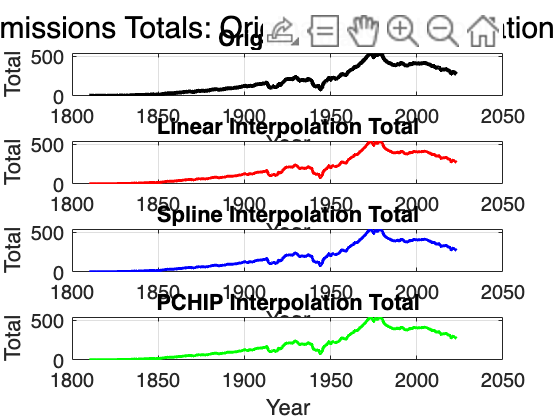


% Extract the year column (adjust if needed)
years = france_data.Year;

% Original total
orig_total = france_data.Total;

% Recomputed totals
linear_total  = france_linear.Total;
spline_total  = france_spline.Total;
pchip_total   = france_pchip.Total;

% --- Plot separately using solid lines, different colors ---
figure;

% Original
subplot(4,1,1);
plot(years, orig_total, 'k-', 'LineWidth', 2);
xlabel('Year'); ylabel('Total');
title('Original Total');
grid on;

% Linear
subplot(4,1,2);
plot(years, linear_total, 'r-', 'LineWidth', 1.5);
xlabel('Year'); ylabel('Total');
title('Linear Interpolation Total');
grid on;

% Spline
subplot(4,1,3);
plot(years, spline_total, 'b-', 'LineWidth', 1.5);
xlabel('Year'); ylabel('Total');
title('Spline Interpolation Total');
grid on;

% PCHIP
subplot(4,1,4);
plot(years, pchip_total, 'g-', 'LineWidth', 1.5);
xlabel('Year'); ylabel('Total');
title('PCHIP Interpolation Total');
grid on;

% Add a shared title
sgtitle('France Emissions Totals: Original and Interpolation Methods');